# Custom Syntax For Formatting Live Scripts

-Khris Griffis

**Change Log**

`13 June 2022` - Inital Creation by KG (MATLAB 2022a R2)

## Introduction

This document describes the syntax for creating an m-file which will be built by the `BUILD` function into 2 different live scripts: one for handing out to students and another as the key. Using the outlined syntax allows the parser to know which code is an answer, which code should be kept, and which text of the document is reserved for copy (informative text). We utilized the [MATLAB Publishing Markup](https://www.mathworks.com/help/matlab/matlab_prog/marking-up-matlab-comments-for-publishing.html) to make the process seemless with existing rules and practices.

For the sake of transparency, and because the MATLAB publisher parser does some quirky things, here are a few basic rules I've come to understand through lots of trial and error:

- Allow a completely blank line before beginning any runnable-code regions.

- Always use a single comment-character for comments in runnable-code regions.

- Be aware of the spaces and new lines! MATLAB parses the `%%` different depending on whether or not there is a new line present.

- When combining multiple formatting markup constructs in a section, it is usually required to place a blank line followed by three consecutive comment characters `%%%`.

Let's get started!

## Protected Code

Protected code is code that should be present in both key and handout versions. Should the teacher wish to persist runnable code the following syntax should be used. Any code blocks, including code comments, will be kept up until the next section break as delimited by two or more consecutive percent-signs (`%%`), or until an Answer Block is reached. That is, you only need to specify if a code block should be kept at the beginning of the block, and not before each line. 

To protect a code block, place the command `%!` at the beginning of the code block.

% DO NOT EDIT
A = [1,2,3;4,5,6];

% This comment is preserved.
table((1:10)',strings(10,1),'VariableNames',{'numbers','strings'})
% This comment is also preserved, even if the Protected Code block results in an
% output.
A .^ 2 %#ok<NOPTS>

## Answers Code Block

While the protected code block ensures that runnable code persists in both key and handout versions, an Answer block is only available in the key version. Answer blocks with be omitted until two or more consecutive comment characters are reached, or until a Protected Code block is reached. Any comments reached AFTER the Answer block command will be eliminated. It is best to avoid relying on comments between multiple-commands answers.

To mark a code block as an Answer block, use the command `%@` at the beginning of the code block.

% DO NOT EDIT
B = A + 10;

% Determine the matrix C which satisfies B .* C = A
% ANSWER BELOW

Note: code blocks that do not contain either Protected or Answer commands will be left alone but will not be marked with DO NOT EDIT. The Protected syntax ensures that student understands the code below is not to be edited.

## MATLAB® Publisher Syntax (review)

The below sections outline the syntax used by MATLAB to create typesetted copy. Many of the below sections described syntax that can be auto-generated from the Publish toolbar:

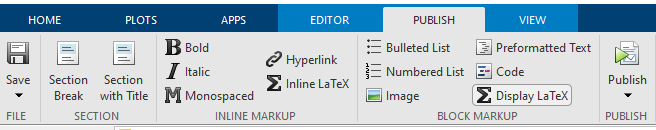

## Sections and Titles

When creating sections, it appears MATLAB will only create an actual break when the previous section contains runnable code.

## Text Formatting

Inline formatting, such as **bold**, *italics*, `monospace`, $\int_1^{20} x^2 dx$, or even


$$\int_1^{20} x^2 dx\mathrm{,}$$


may be produced by bracketing text with following syntax:

## Formatted Example Code

A formatted code block is a block of code which will be treated as display-only. This means that any formatted code blocks will have a monospaced font. Depending on the number of spaces used

A formatted code block requires 3 spaces before the first line of code. Any code indentations beyond this must be relative to the 3-space margin. For example, when placing 2 spaces after the `%`, the code,

produces the following output:

Further, when placing 3 spaces after the `%` character,

the parse produces syntax highlighted code in the output:

## Including Figures/Images And Hyperlinks

To include an image, the image path must be written relative to the script. For example, in the `examples/lib/img` folder, there is an image called `peaks.png`. To include this file in the documents, we must use the image syntax with the relative file path, like so:

produces: 

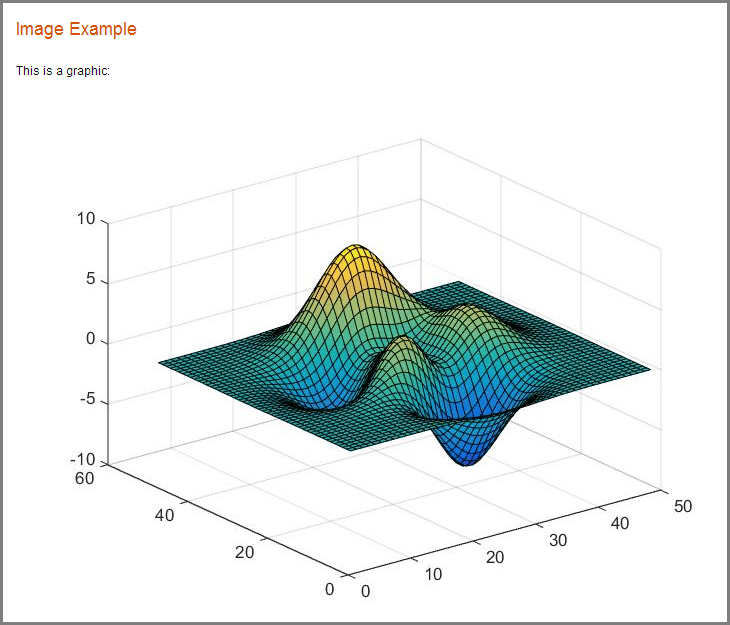

Note: The image will be displayed at full resolution in the final live script, so make sure your images is around a few hundred pixels on the long edge to prevent strange appearance in the live script.

MATLAB seems to alright if the image is a `*``.png` or `*``.jpg` file but will have issues with `*``.svg` and other vector formats.

When including hyperlinks, there are two types of hyperlink formats to consider.

The above produces a link with an alias, [MathWorks Site](https://www.mathworks.com), while the one below will produce a link and show the full link: [https://www.mathworks.com](https://www.mathworks.com).

## Lists

Bulleted lists can be made in the following way:

which will produce: 

- BULLETED ITEM 1

- BULLETED ITEM 2

Numbered lists can be made in the following way:

which will produce: 

- NUMBERED ITEM 1

- NUMBERED ITEM 2